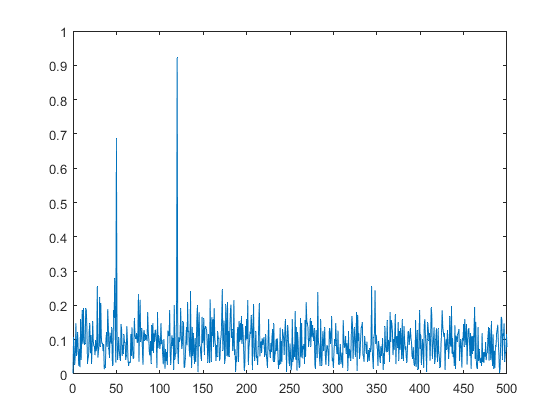

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector
S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
X = S + 2*randn(size(t));
Y = fft(X);
P = abs(Y)/L;
P = P(1:L/2+1);
P(2:end-1) = 2*P(2:end-1);
f = 0:Fs/L:Fs/2;
figure;
plot(f,P);